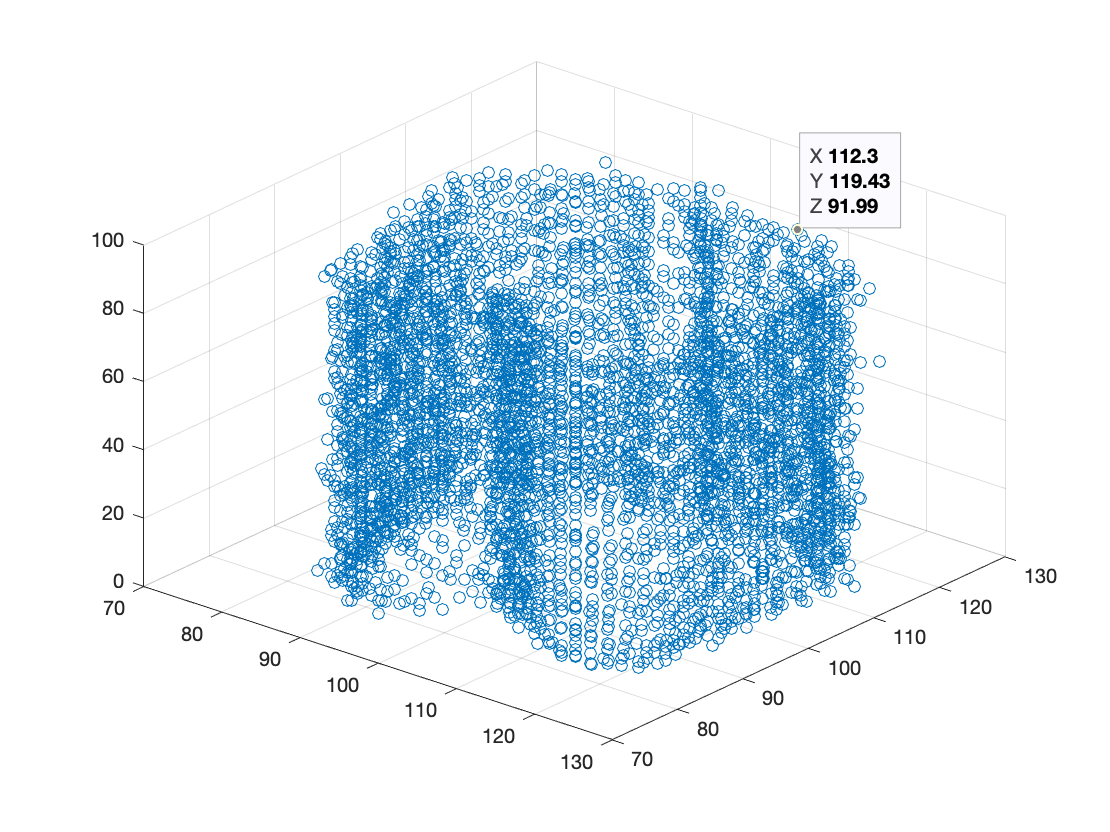

device = serialport("/dev/tty.usbmodem14403", 921600);

% Receive points from Scanner.
x = [];
y = [];
z = [];
x_temp = 0; y_temp = 0; z_temp = 0;
n = 1;
while x_temp ~= -100 && y_temp ~= -100 && z_temp ~= -100
   data = device.read(3, 'int16');
    if length(data) == 3
        x_temp = data(1);y_temp = data(2);z_temp = data(3);
        if x_temp ~= -100 && y_temp ~= -100 && z_temp ~= -100
            x = [x (x_temp / 100.0)];y = [y (y_temp / 100.0)];z = [z (z_temp / 100.0)];
            scatter3(x,y,z)
            view(40,35)
            n = n + 1;
        end
    end
end


% Receive STL-Data from Scanner
fileID = fopen('sample.stl', 'w');
eof = false;
str = fprintf(fileID, "solid scan\n");
while eof == false
    try
        data = device.read(12, 'int16') ./ 100.0;
        fprintf(fileID, "\tfacet normal %.2f %.2f %.2f\n", data(1), data(2), data(3));
        fprintf(fileID, "\t\touter loop\n");
        fprintf(fileID, "\t\t\tvertex %.2f %.2f %.2f\n", data(4), data(5), data(6));
        fprintf(fileID, "\t\t\tvertex %.2f %.2f %.2f\n", data(7), data(8), data(9));
        fprintf(fileID, "\t\t\tvertex %.2f %.2f %.2f\n", data(10), data(11), data(12));
        fprintf(fileID, "\t\tendloop\n");
        fprintf(fileID, "\tendfacet\n");
    catch err
        eof = true;
    end
end

fprintf(fileID, "endsolid scan");
fclose(fileID);

% Close Serial connection.
device = [];